# Double-Mass-Spring-Damper System

## Problem Description

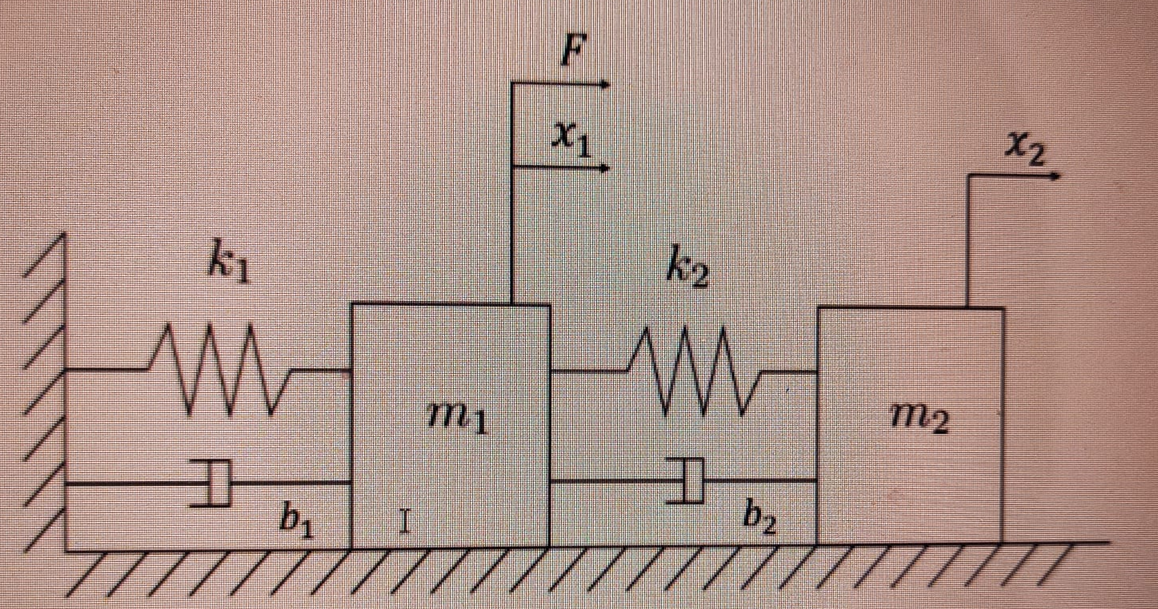

The system consists of two masses m_1 and m_2 with each having a spring and damper connecting them to a stationary wall and mass m_1 respectively. An input force F is applied on m_1 which causes both masses to oscillate due to the nature of the system.

The system will be simulated in a simscape environment, simulink environment and as transfer functions.

## Variable Declaration

m_1 =1;                                % mass 1 in kg
m_2 =1;                                % mass 2 in kg
b_1 = 1;                              % damper 1 constant in N/ms^-1
k_1 = 1;                              % stiffness of spring 1 in N/m
b_2 = 1;                              % damper 2 constant in N/ms^-1
k_2 = 1;                              % stiffness of spring 2 in N/m
F_in = 1;                             % input force in N
simtime = 30;                                                 % runtime in s

## Simulation

sim('Capstone_project_4.slx')

## Graph Plots

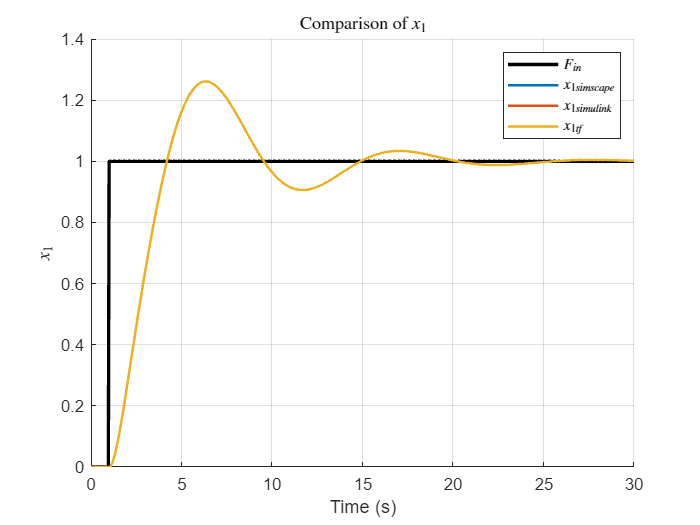

% Extract signals
x_1_simscape.data = reshape(x_1_simscape.data, [], 1);
x_2_simscape.data = reshape(x_2_simscape.data, [], 1);
x_1_dot_simscape.data = reshape(x_1_dot_simscape.data, [], 1);
x_2_dot_simscape.data = reshape(x_2_dot_simscape.data, [], 1);

colors = lines(3); % Use MATLAB's built-in color scheme

%% Figure 1: x_1 comparison
figure;
hold on; grid on;
plot(IN.time, IN.data, 'k-', 'LineWidth', 2, 'DisplayName', '$F_{\text{in}}$');
plot(x_1_simscape.time, x_1_simscape.data, 'Color', colors(1,:), 'LineWidth', 1.5, 'DisplayName', '$x_1$ (Simscape)');
plot(x_1_simulink.time, x_1_simulink.data, 'Color', colors(2,:), 'LineWidth', 1.5, 'DisplayName', '$x_1$ (Simulink)');
plot(x_1_tf.time, x_1_tf.data, 'Color', colors(3,:), 'LineWidth', 1.5, 'DisplayName', '$x_1$ (TF)');
xlabel('Time (s)'); ylabel('$x_1$', 'Interpreter', 'latex');
title('Comparison of $x_1$', 'Interpreter', 'latex');
legend('$F_{in}$', '$x_{1simscape}$', '$x_{1simulink}$', '$x_{1tf}$', 'Interpreter', 'latex'); hold off;

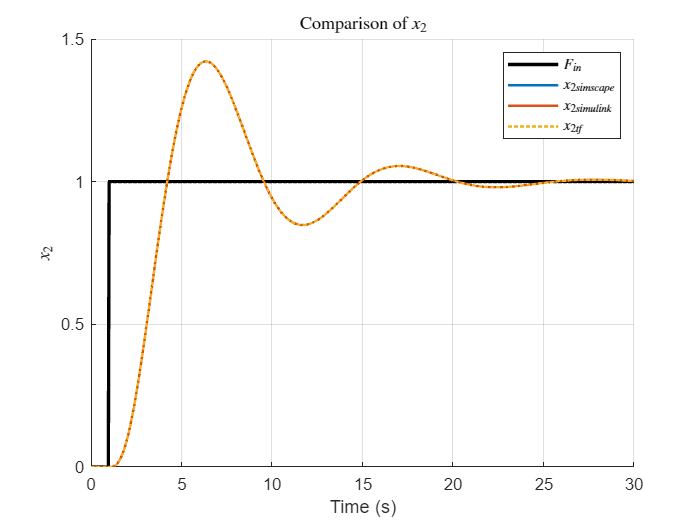


%% Figure 2: x_2 comparison
figure;
hold on; grid on;
plot(IN.time, IN.data, 'k-', 'LineWidth', 2, 'DisplayName', '$F_{\text{in}}$');
plot(x_2_simscape.time, x_2_simscape.data, 'Color', colors(1,:), 'LineWidth', 1.5, 'DisplayName', '$x_2$ (Simscape)');
plot(x_2_simulink.time, x_2_simulink.data, 'Color', colors(2,:), 'LineWidth', 1.5, 'DisplayName', '$x_2$ (Simulink)');
plot(x_2_tf.time, x_2_tf.data, styles{3}, 'Color', colors(3,:), 'LineWidth', 1.5, 'DisplayName', '$x_2$ (TF)');
xlabel('Time (s)'); ylabel('$x_2$', 'Interpreter', 'latex');
title('Comparison of $x_2$', 'Interpreter', 'latex');
legend('$F_{in}$', '$x_{2simscape}$', '$x_{2simulink}$', '$x_{2tf}$', 'Interpreter', 'latex'); hold off;

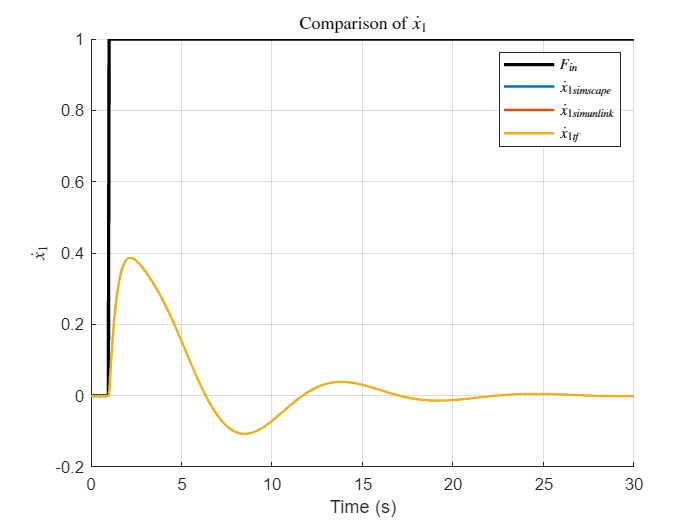


%% Figure 3: x_1_dot comparison
figure;
hold on; grid on;
plot(IN.time, IN.data, 'k-', 'LineWidth', 2, 'DisplayName', '$F_{\text{in}}$');
plot(x_1_dot_simscape.time, x_1_dot_simscape.data, 'Color', colors(1,:),'LineWidth', 1.5, 'DisplayName', '$\dot{x}_1$ (Simscape)');
plot(x_1_dot_simulink.time, x_1_dot_simulink.data, 'Color', colors(2,:), 'LineWidth', 1.5, 'DisplayName', '$\dot{x}_1$ (Simulink)');
plot(x_1_dot_tf.time, x_1_dot_tf.data, 'Color', colors(3,:), 'LineWidth', 1.5, 'DisplayName', '$\dot{x}_1$ (TF)');
xlabel('Time (s)'); ylabel('$\dot{x}_1$', 'Interpreter', 'latex');
title('Comparison of $\dot{x}_1$', 'Interpreter', 'latex');
legend('$F_{in}$', '$\dot{x}_{1simscape}$', '$\dot{x}_{1simunlink}$', '$\dot{x}_{1tf}$', 'Interpreter', 'latex'); hold off;

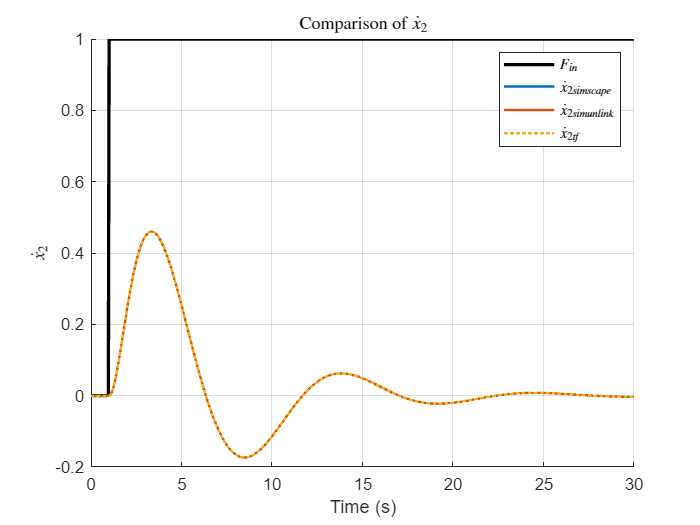


%% Figure 4: x_2_dot comparison
figure;
hold on; grid on;
plot(IN.time, IN.data, 'k-', 'LineWidth', 2, 'DisplayName', '$F_{\text{in}}$');
plot(x_2_dot_simscape.time, x_2_dot_simscape.data, 'Color', colors(1,:), 'LineWidth', 1.5, 'DisplayName', '$\dot{x}_2$ (Simscape)');
plot(x_2_dot_simulink.time, x_2_dot_simulink.data, 'Color', colors(2,:), 'LineWidth', 1.5, 'DisplayName', '$\dot{x}_2$ (Simulink)');
plot(x_2_dot_tf.time, x_2_dot_tf.data, styles{3}, 'Color', colors(3,:), 'LineWidth', 1.5, 'DisplayName', '$\dot{x}_2$ (TF)');
xlabel('Time (s)'); ylabel('$\dot{x}_2$', 'Interpreter', 'latex');
title('Comparison of $\dot{x}_2$', 'Interpreter', 'latex');
legend('$F_{in}$', '$\dot{x}_{2simscape}$', '$\dot{x}_{2simunlink}$', '$\dot{x}_{2tf}$', 'Interpreter', 'latex'); hold off;